% load('Controllers/PolePlacementWout/DT_SS_model_G1.mat')
load('Controllers/PolePlacementWout/wb_upup_lin.mat')
% A = G1.A
% B = G1.B
% C = G1.C
% D = G1.D

A = sys.A

A =   -50.0000         0         0         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000
   49.7300    2.5640   -1.7770 -419.8000    0.0023
 -109.5000  124.5000  134.1000  924.2000   -0.0972


B = sys.B

B = 	1.0e+03 *

   -2.9990
         0
         0
         0
         0


C = sys.C

C =      0     1     0     0     0
     0     0     1     0     0


D = sys.D

D =      0
     0


Load ss matrices

% A = [       -50,        0,         0,        0,       0;
%               0,        0,         1,        0,       0;
%         49.7348,   2.5645, -419.7870,  -1.7769,  0.0023;
%               0,        0,         0,        0,       1;
%       -109.4970, 124.5290,  924.2091, 134.0870, -0.0972];
%  
% B = [-2.9990e+03; 0; 0; 0; 0]
% 
% C = [0 1 0 0 0;
%      0 0 0 1 0];
%  
% D = [0; 0];

create state space object

% sys = ss(A, B, C, D)
% sys = d2c(sys)

check controlable

Co = ctrb(sys)

Co = 	1.0e+13 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0019
         0         0   -0.0000    0.0000   -0.0030
         0         0    0.0000   -0.0000    0.0066
         0   -0.0000    0.0000   -0.0030    1.2524
         0    0.0000   -0.0000    0.0066   -2.7589


unco = length(A) - rank(Co)

unco = 0

check open loop eigenvalues

E = eig(A)

E =  -419.8205
   11.3664
  -11.4535
    0.0103
  -50.0000


Desired closed loop eigenvalues

% P = [-0.1 -0.2 -0.3 -0.4 -0.6 -0.8]
P = [-0.1 -0.2 -0.3 -0.4 -0.8];

solve for K

K = place(A, B, P)

K =     0.1561    0.0084   -0.0038   -1.1762    0.0007


check for closed loop eigenvalues

A_cl = A - B*K

A_cl = 	1.0e+03 *

    0.4181    0.0252   -0.0113   -3.5273    0.0022
         0         0         0    0.0010         0
         0         0         0         0    0.0010
    0.0497    0.0026   -0.0018   -0.4198    0.0000
   -0.1095    0.1245    0.1341    0.9242   -0.0001


Create closed loop system

syscl = ss(A_cl, B, C, D)


syscl =
 
  A = 
            x1       x2       x3       x4       x5
   x1    418.1    25.16   -11.33    -3527    2.248
   x2        0        0        0        1        0
   x3        0        0        0        0        1
   x4    49.73    2.564   -1.777   -419.8   0.0023
   x5   -109.5    124.5    134.1    924.2  -0.0972
 
  B = 
          u1
   x1  -2999
   x2      0
   x3      0
   x4      0
   x5      0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   1   0   0   0
   y2   0   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



% syscl = c2d(syscl)
% sys = c2d(sys)

check step response

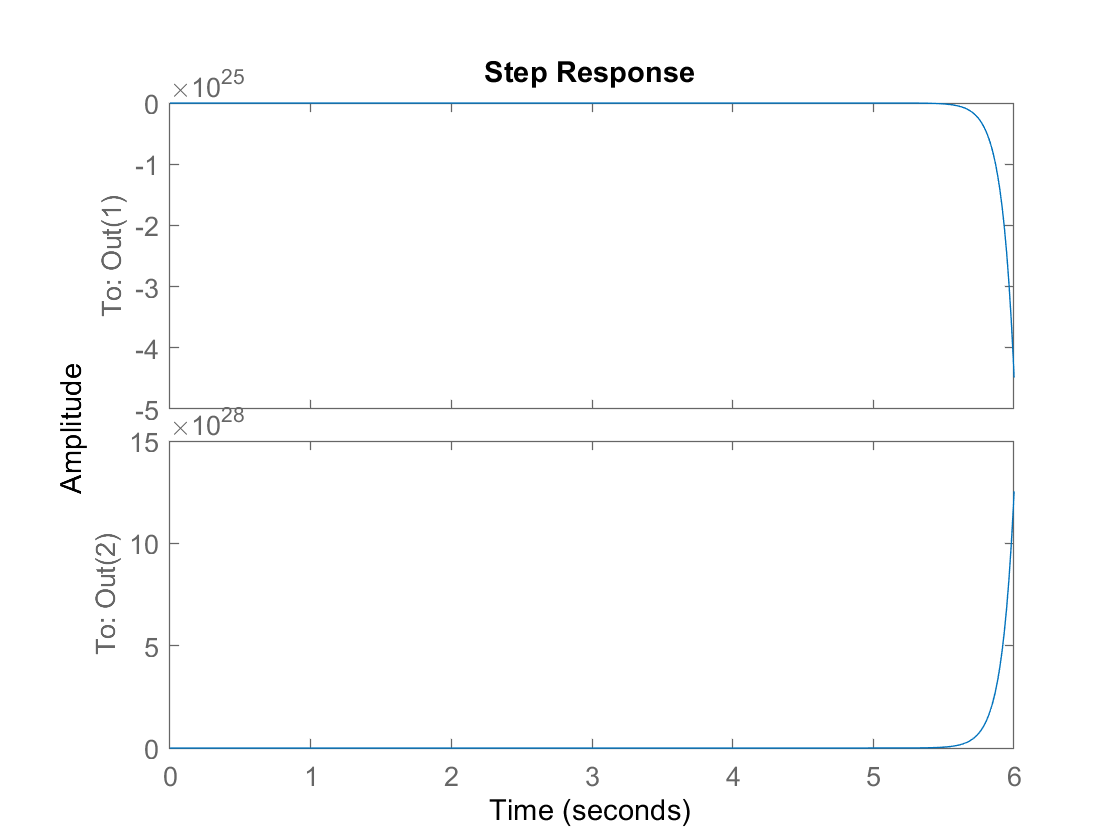

step(sys)

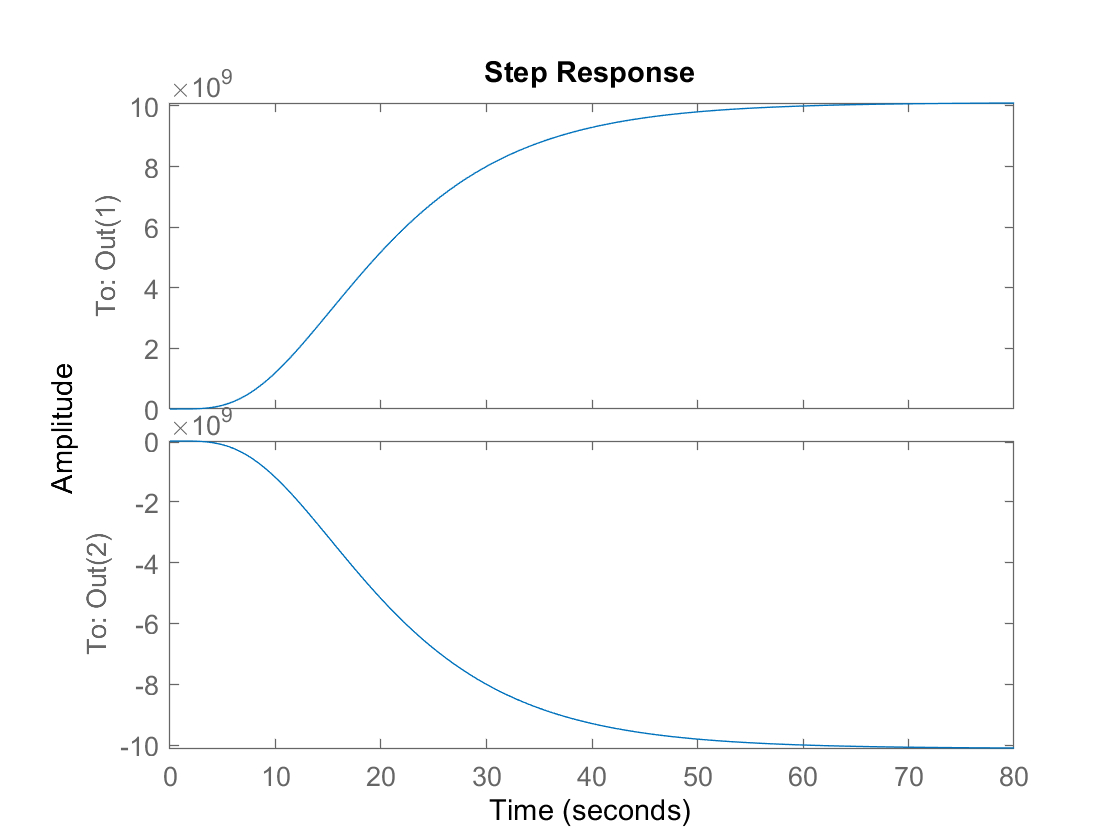

step(syscl)